# Goal

In this practice we will use a neuron network to classify images. We will additionnally use the Gabor filter and  reduce the images to better detect the features.

# Previous practices, what is needed

- Gabor kernel Filter (gabor_kernel, gabor_reduce, gabor_template)

- Reduce Image (reduce_image)

- MLP with the necessary functions (GetError_class.m, sigmoid.m, sigmoidGradient.m, learningNN_class.m, gradientNN_class.m) and the parameters (iterations, number of neurons in the hidden layer, alpha)

General schema:

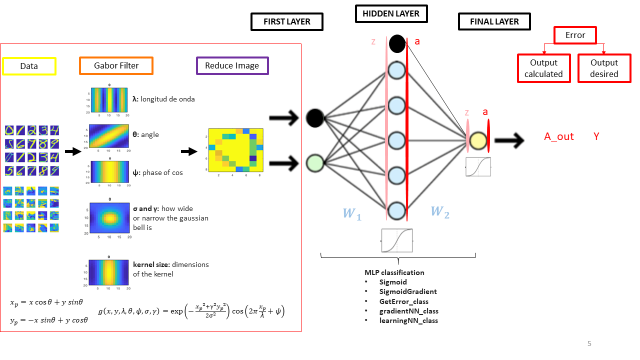

%% load CIFAR dataset 

clear 
clear all


% classes:
% 0:    'airplane'
% 1:    'automobile'
% 2:    'bird'
% 3:    'cat'
% 4:    'deer'
% 5:    'dog'
% 6:    'frog'
% 7:    'horse'
% 8:    'ship'
% 9:    'truck'
% 10:   'galaxy'

%% Choose 2 digits between 0 and 9:
class1 = 6;
name1 = 'frog';
class2 = 3;
name2 = 'cat';
class3 = 7;
name3 = 'horse';

num_pattern = 500;  % for example 300, max 10000, if all the patterns are used the training is very long


% NO modifition (this function separates trainset, data, and testset, data_val) for the 2 classes chosen



[data,data_val,Ytrain,Yval]=GetDataimages(class1, class2,class3,num_pattern);

% data: data of the training set
% data_val: data of the validation set
% Ytrain: tags of the training data set
% Yval: tags of the validation data set


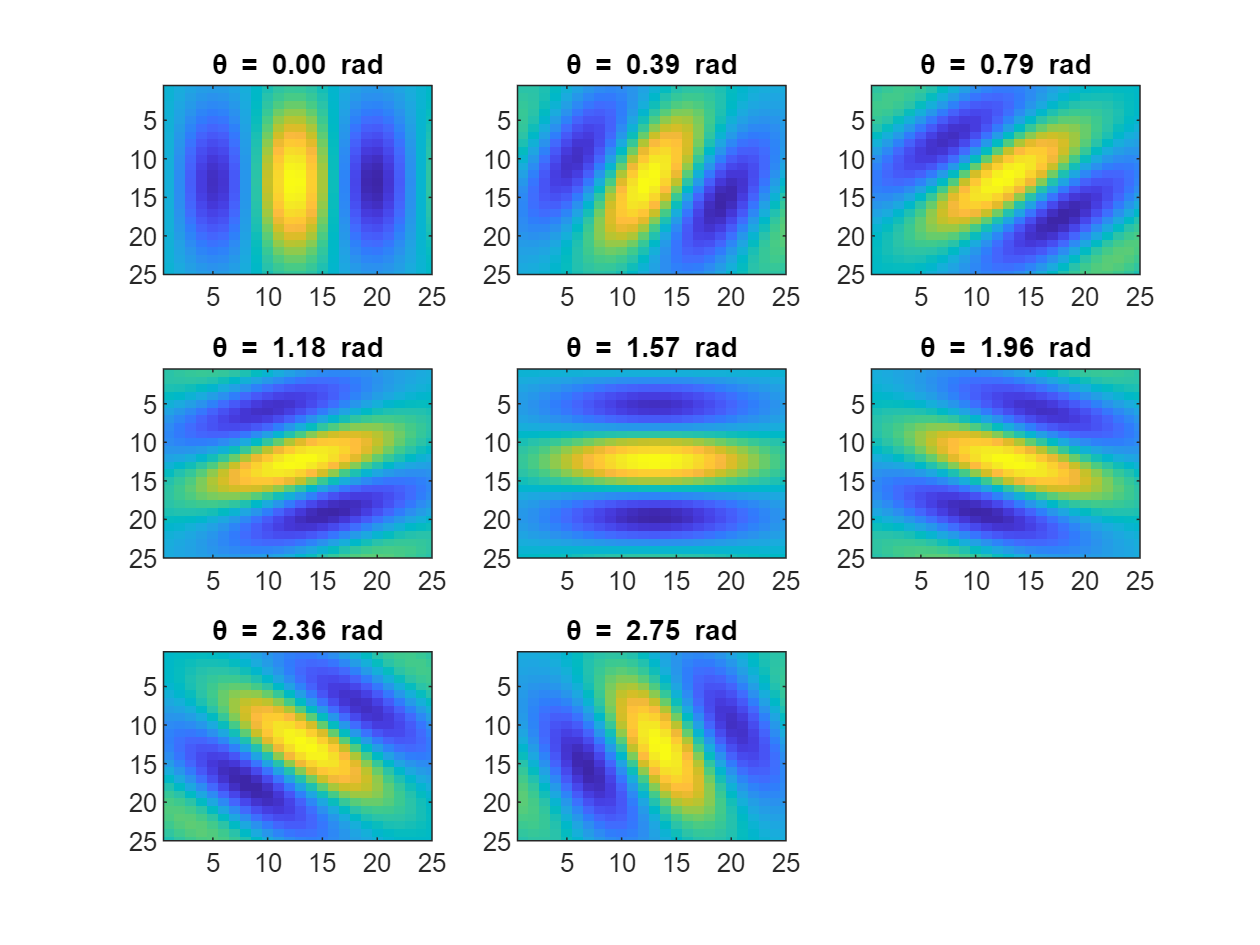

%% Choose the parameters of the Gabor filters
kern_size = 25;  % Kernel size
lambda = 9;     % wavelength (1/frequency)
phi = 0.25;        % phase offset
sigma = 5;      % Gaussian dispersion
gamma = 0.95;    % height / amplitude ratio

% NO modification:
fig = false;
orientations = [0*pi/8, 1*pi/8, 2*pi/8, 3*pi/8, 4*pi/8, 5*pi/8, 6*pi/8, 7*pi/8]; %orientaciones de los filtros
image_size = [32 32 3];  %size of the original images
reduction_factor = 16;

% Convolution of training data:
Xtrain = gabor_reduce(data, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,true);

% Convolution of validation data:
Xval = gabor_reduce(data_val, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,false);

In this practice we will need more neurons in the input layer than in practice 3. Make sure gradientNN_class.m considers this (W1_grad = d_h*x');

%%  MLP

% Choose the parameters of the neural network:
hidden_units = 50;
max_iter = 1000;
alpha = 0.01;

% Gradient Descent: call the learning function
[E, E_val, W1, W2, ct] = learningNN_class( Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter );

As in practice 3, we next evaluate the classifier by seeing how many patterns are correctly classified. The variable **pred** (prediction) will be worth 0 or 1 depending on whether the predicted class is 1 or 2. To do this we set the values of **y** that are equal to 0 below 0.5 and those of 1 above 0.5.

%% Predict classification with training data
pred_t = zeros(size(Xtrain,2),1);
y = zeros(size(Xtrain,2),1);
for p = 1:size(Xtrain,2)  % pattern loop       
    x = Xtrain(:,p); % % sample entry p
    % calculate activation for hidden neurons:
    z_h = W1*x;  % sum before the sigmoid
    a_h = sigmoid(z_h);  % activation of hidden neurons
    a_h = [1;a_h];  % add the neuron whose value is always equal to one and that serves as bias to the next layer

    % Calculate activation of the output neuron:
    z_out = W2*a_h;  % sum before the output neuron response function
    y(p) = sigmoid(z_out);  % calculate output neuron response (regression: identity - classification: logistic sigmoid)
    if y(p) > 2/3
        pred_t(p) = 2;
    elseif y(p) < 1/3
        pred_t(p) = 0;
    else
        pred_t(p) = 1;
    end
end   

correct = sum(pred_t==Ytrain)/length(Ytrain);
display(['Porcentage de clasificaciones correctas en entrenamiento: ' num2str(correct(1))] )

Porcentage de clasificaciones correctas en entrenamiento: 0.41333



class1_t = sum(Ytrain==1);
class2_t = sum(Ytrain==0);
class3_t = sum(Ytrain==2);
cor_class1 = sum(pred_t(Ytrain==1)==1)/class1;
cor_class2 = sum(pred_t(Ytrain==0)==0)/class2;
cor_class3 = sum(pred_t(Ytrain==2)==2)/class3;

%% Predict classification with validation data
numpattval = size(Xval,2);
yval = zeros(numpattval,1);
pred_val = zeros(numpattval,1);
for p = 1:numpattval  % pattern loop       
    x = Xval(:,p); % sample entry for patterns p
    % calculate activation for hidden neurons:
    z_h = W1*x;  % sum before the sigmoid
    a_h = sigmoid(z_h);  % activation of hidden neurons
    a_h = [1;a_h];  % add the neuron whose value is always equal to one and that serves as bias to the next layer

    % Calculate activation of the output neuron:
    z_out = W2*a_h;  % sum before the output neuron response function
    yval(p) = sigmoid(z_out);  % calculate output neuron response (regression: identity - classification: logistic sigmoid)  
    if yval(p) > 2/3
        pred_val(p) = 2;
    elseif yval(p) < 1/3
        pred_val(p) = 0;
    else
        pred_val(p) = 1;
    end
end   


%pred_val = yval > 0.5;
correct = sum(pred_val==Yval)/length(Yval);
display(['Porcentage de clasificaciones correctas en validacion: ' num2str(correct(1))] )

Porcentage de clasificaciones correctas en validacion: 0.39375



class1_val = sum(Yval==1);
class2_val = sum(Yval==0);
class3_val = sum(Yval==2);
cor_class1_val = sum(pred_val(Yval==1)==1)/class1_val;
cor_class2_val = sum(pred_val(Yval==0)==0)/class2_val;
cor_class3_val = sum(pred_val(Yval==2)==2)/class3_val;


Visualization of the accuracy of the MLP to classify training and validation data:

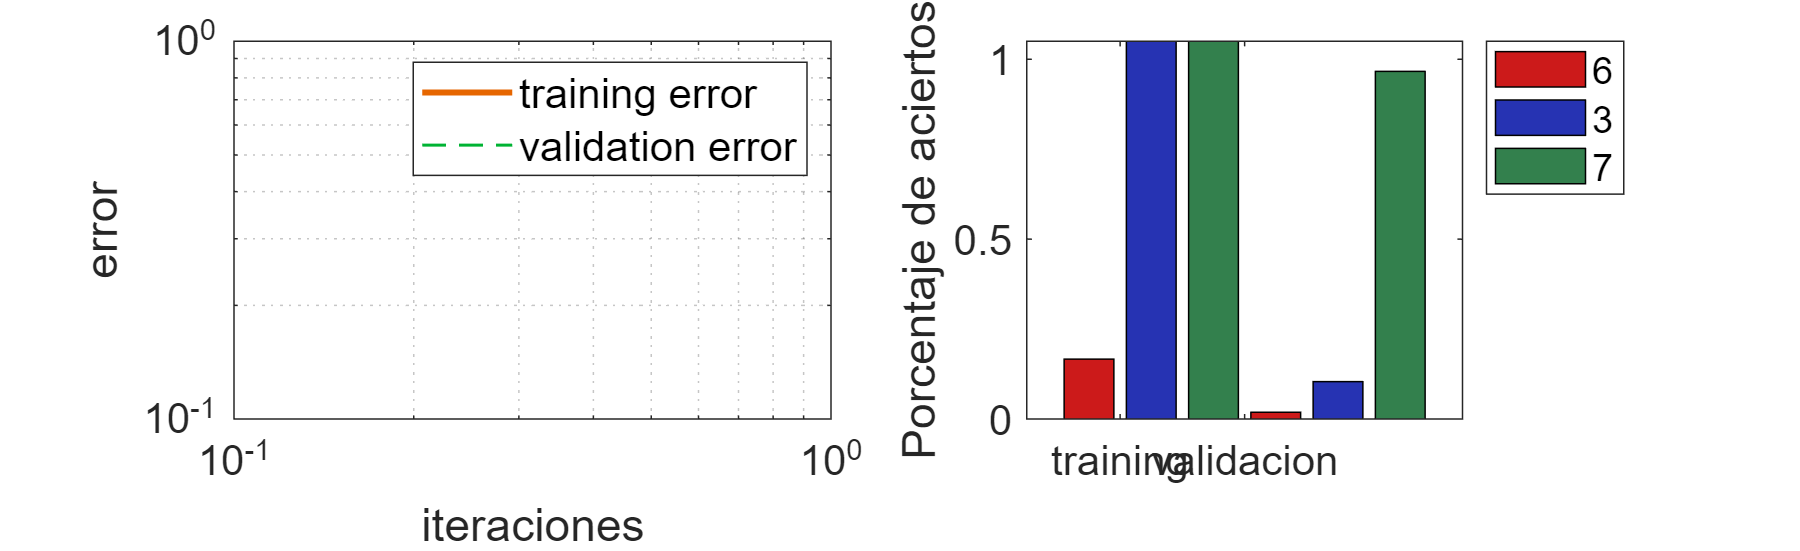

%Plot error and predictions
figure('NumberTitle', 'off', 'Name', 'Error and Predictions');
set(gcf,'units','normalized','position',[0,0.25,1,0.4])

subplot(121),cla
plot(E, 'color', [.9 .4 0], 'linewidth', 2), hold on
plot(E_val, '--','color', [.0 .7 .2], 'linewidth', 1)
xlabel('iteraciones', 'fontsize', 14)
ylabel('error', 'fontsize', 14)
legend({'training error', 'validation error'}, 'fontsize', 14)
set(gca, 'fontsize', 14,'yscale','log','xscale','log'), grid on

subplot(122),cla
bar(1, cor_class1,'facecolor', [.8 .1 .1])
hold on
bar(2, cor_class2,'facecolor', [.15 .2 .7])
bar(3, cor_class3,'facecolor', [.2 .5 .3])
bar(4, cor_class1_val,'facecolor', [.8 .1 .1])
bar(5, cor_class2_val, 'facecolor', [.15 .2 .7])
bar(6, cor_class3_val, 'facecolor', [.2 .5 .3])
ylabel('Porcentaje de aciertos', 'fontsize', 14), ylim([0, 1.05])
legend(num2str(class1),num2str(class2),num2str(class3),'location','bestoutside'),xlim([0 7])
set(gca, 'fontsize', 14, 'XTick', [1.5,3.5],'XTickLabel',{['training'], 'validacion'} )

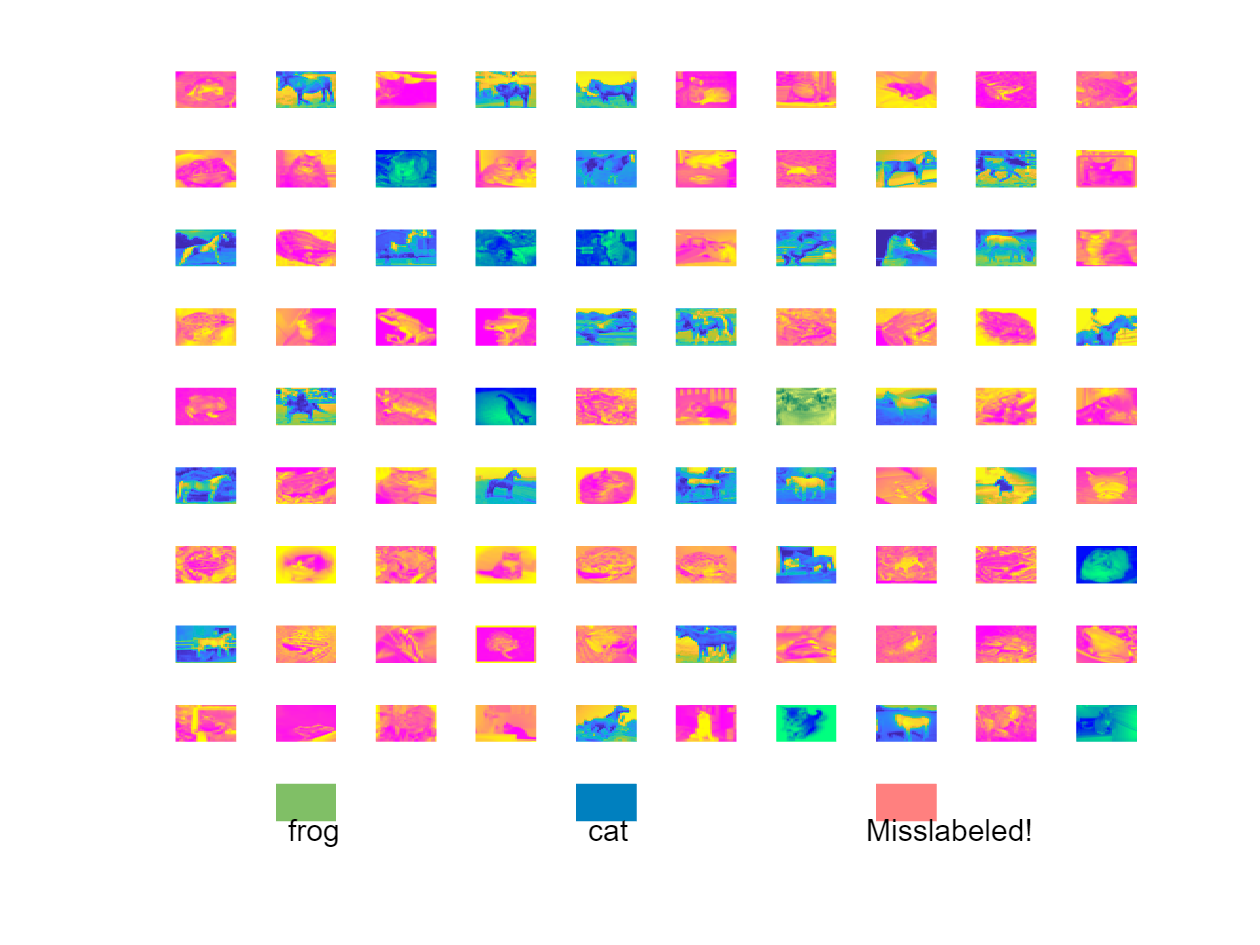

%Plot Predictions
figure('NumberTitle', 'off', 'Name', 'Training Predictions');
for i = 1:90 % # de ejemplos mostrados
    if i<size(data,1)
   ax1 = subplot(10,10,i);
   img = reshape(data(i,:), image_size);
   img = sum(img, 3);
   img = img';
   imagesc(img);
   axis off
   if pred_t(i) == 1
      colormap(ax1, summer)
   end
   if pred_t(i) == 0
      colormap(ax1, winter)
   end
   if pred_t(i) ~= Ytrain(i)
      colormap(ax1, spring)
   end
    end
end
ax1 = subplot(10,10,92);
imagesc(zeros(32,32));
colormap(ax1, summer)
axis off
text(7 ,40, name1)
ax1 = subplot(10,10,95);
imagesc(zeros(32,32));
colormap(ax1, winter)
axis off
text(7 ,40, name2)
ax1 = subplot(10,10,98);
imagesc(zeros(32,32));
colormap(ax1, spring)
axis off
text(-5 ,40, 'Misslabeled!')

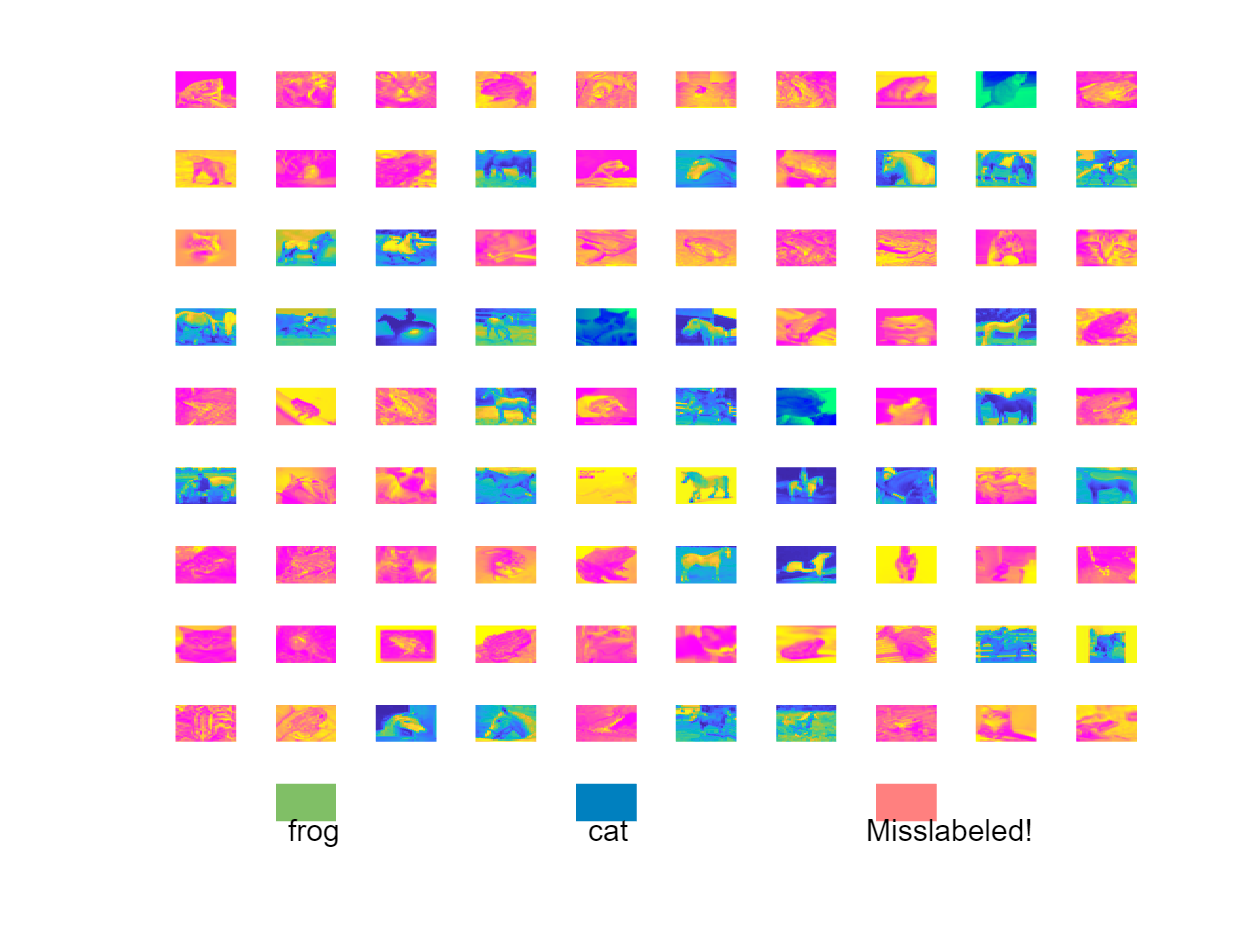


figure('NumberTitle', 'off', 'Name', 'Validation Predictions');
for i = 1:90 %# de ejemplos mostrados
    if i<size(data_val,1)
   ax1 = subplot(10,10,i);
   img = reshape(data_val(i,:), image_size);
   img = sum(img, 3);
   img = img';
   imagesc(img);
   axis off
   if pred_val(i) == 1
      colormap(ax1, summer)
   end
   if pred_val(i) == 0
      colormap(ax1, winter)
   end
   if pred_val(i) ~= Yval(i)
      colormap(ax1, spring)
   end
    end
end
ax1 = subplot(10,10,92);
imagesc(zeros(32,32));
colormap(ax1, summer)
axis off
text(7 ,40, name1)
ax1 = subplot(10,10,95);
imagesc(zeros(32,32));
colormap(ax1, winter)
axis off
text(7 ,40, name2)
ax1 = subplot(10,10,98);
imagesc(zeros(32,32));
colormap(ax1, spring)
axis off
text(-5 ,40, 'Misslabeled!')